# Demo 1: wczytywanie danych (loadCoco)

Skrypt pokazuje, skąd biorą się dane wejściowe całego procesu: jak wygląda plik adnotacji COCO, co zwraca funkcja loadCoco oraz jakie są statystyki zbioru Mlekolaki v3 (liczność klas, rozmiary obiektów).

## Konfiguracja ścieżek

Skrypt zakłada, że leży w segmentation/demo/, a dane w data/ w katalogu głównym repozytorium. Działa niezależnie od bieżącego folderu MATLAB-a. W Live Editorze mfilename wskazuje na plik tymczasowy w /tmp, dlatego sprawdzamy kilka możliwych lokalizacji skryptu i wybieramy tę, dla której istnieje folder data/ dwa poziomy wyżej.

candidates = string(fileparts(mfilename("fullpath")));
try
    candidates(end+1) = fileparts(matlab.desktop.editor.getActiveFilename);
catch
end
candidates(end+1) = pwd;
candidates = candidates(candidates ~= "");
ok = arrayfun(@(d) isfolder(fullfile(d, "..", "..", "data")), candidates);
assert(any(ok), "Nie znaleziono folderu data/. Ustaw Current Folder na segmentation/demo.")
demoDir = candidates(find(ok, 1));
segDir  = fileparts(demoDir);
addpath(segDir);
dataDir = fullfile(segDir, "..", "data", "Mlekolaki.v3i.coco");

classNames = ["choco", "cookie", "corn"];
colors = [0.85 0.2 0.2; 0.2 0.5 0.95; 0.95 0.85 0.1];

## Krok 1: surowy plik adnotacji

Plik _annotations.coco.json zawiera trzy główne listy: images (obrazy), annotations (ramki) i categories (klasy). Kategoria 0 "creams" to nadkategoria dodana przez Roboflow i nie jest używana w żadnej ramce.

raw = jsondecode(fileread(fullfile(dataDir, "train", "_annotations.coco.json")));
disp(fieldnames(raw))

    {'info'       }
    {'licenses'   }
    {'categories' }
    {'images'     }
    {'annotations'}



struct2table(raw.categories)

ans = 4×3 table
    id       name       supercategory
    __    __________    _____________

    0     {'creams'}     {'none'  }  
    1     {'choco' }     {'creams'}  
    2     {'cookie'}     {'creams'}  
    3     {'corn'  }     {'creams'}  


Przykładowa adnotacja. bbox ma postać [x y w h] w pikselach, gdzie (x, y) to lewy górny róg ramki.

raw.annotations(1)

ans = struct with fields:
              id: 1
        image_id: 0
     category_id: 2
            bbox: [4×1 double]
         iscrowd: 0
            area: 923
    segmentation: []


## Krok 2: wczytanie podzbiorów funkcją loadCoco

loadCoco zamienia JSON na prostą tablicę struktur: jeden element na obraz, z polami file, boxes (Nx4) i labels (Nx1).

train = loadCoco(fullfile(dataDir, "train"));
valid = loadCoco(fullfile(dataDir, "valid"));
test  = loadCoco(fullfile(dataDir, "test"));
train(1)

ans = struct with fields:
      file: "/home/jdobr/Programing/pw/psw/segmentation/../data/Mlekolaki.v3i.coco/train/Video1_mp4-82_jpg.rf.ec346bbbec1ff4a72cecd8c2580c9abc.jpg"
     boxes: [83×4 double]
    labels: [83×1 double]


Podsumowanie podzbiorów: liczba obrazów i obiektów.

nObj = @(ds) sum(arrayfun(@(s) numel(s.labels), ds));
summary = table(["train"; "valid"; "test"], ...
    [numel(train); numel(valid); numel(test)], ...
    [nObj(train); nObj(valid); nObj(test)], ...
    'VariableNames', ["podzbior", "obrazy", "obiekty"])

summary = 3×3 table
    podzbior    obrazy    obiekty
    ________    ______    _______

    "train"      144       11026 
    "valid"        6         373 
    "test"        13         780 


## Krok 3: obraz z ramkami wzorcowymi

Kolory ramek: czerwony = choco, niebieski = cookie, żółty = corn.

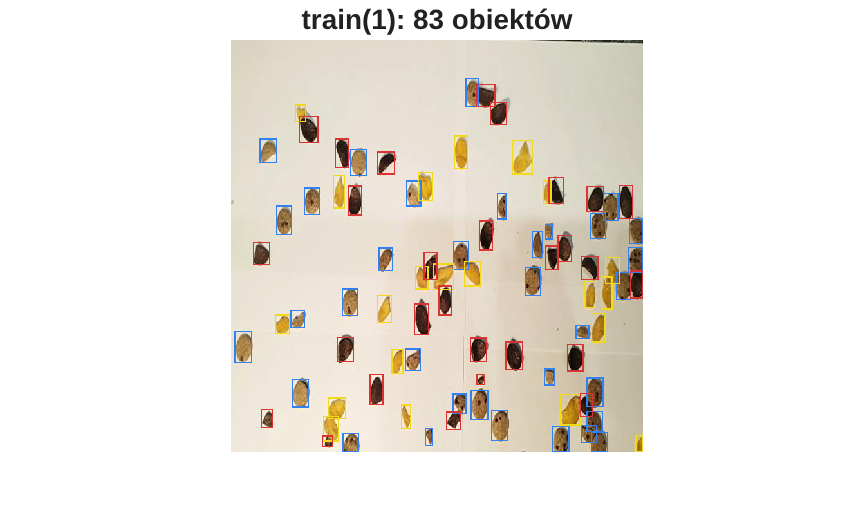

i = 1;
I = imread(train(i).file);
figure
imshow(insertShape(I, "rectangle", train(i).boxes, ...
    "Color", colors(train(i).labels, :) * 255, "LineWidth", 2))
title(sprintf("train(%d): %d obiektów", i, numel(train(i).labels)))

## Krok 4: liczność klas w podzbiorach

Klasy są w miarę zrównoważone, najmniej jest corn.

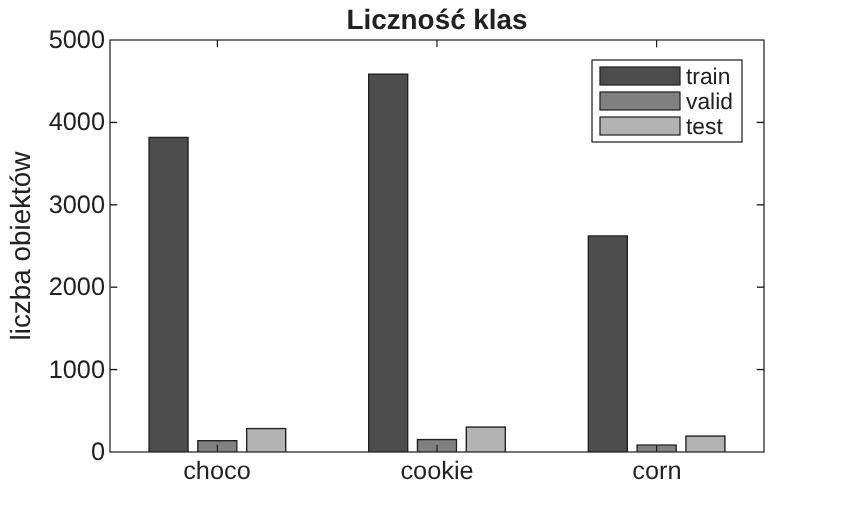

counts = [histcounts(vertcat(train.labels), 0.5:3.5); ...
          histcounts(vertcat(valid.labels), 0.5:3.5); ...
          histcounts(vertcat(test.labels),  0.5:3.5)];
figure
b = bar(counts.');
for c = 1:3, b(c).FaceColor = [0.3 0.3 0.3] + 0.2 * (c - 1); end
xticklabels(classNames); ylabel("liczba obiektów")
legend(["train", "valid", "test"], "Location", "northeast")
title("Liczność klas")

## Krok 5: rozmiary obiektów

Rozmiar obiektu jako pierwiastek z pola ramki. Pomaga dobrać parametry morfologii (np. minArea w segmentImage, dysk w preprocess).

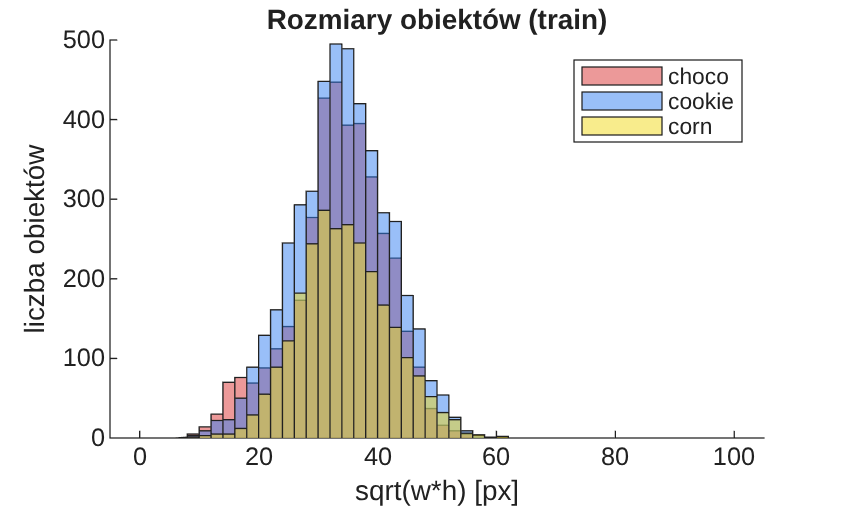

boxes  = vertcat(train.boxes);
labels = vertcat(train.labels);
sz = sqrt(boxes(:, 3) .* boxes(:, 4));
figure; hold on
for c = 1:3
    histogram(sz(labels == c), 0:2:100, "FaceColor", colors(c, :), "FaceAlpha", 0.5)
end
hold off
xlabel("sqrt(w*h) [px]"); ylabel("liczba obiektów")
legend(classNames); title("Rozmiary obiektów (train)")

fprintf("Mediana rozmiaru: %.1f px, min: %.1f px, max: %.1f px\n", ...
    median(sz), min(sz), max(sz));

Mediana rozmiaru: 34.0 px, min: 7.1 px, max: 60.5 px
